This is a model identification exercise for Clemson Clearpath Husky. The model is to be of moderate fidelity such that it can be used for Husky control tasks. Following papers were refered for boot strapping.

[1] Yu, W., Chuy, O., Collins, E., & Hollis, P. (2009). *Dynamic Modeling of a Skid-Steered Wheeled Vehicle with Experimental Verification*. [https://doi.org/10.1109/IROS.2009.5354381](https://doi.org/10.1109/IROS.2009.5354381)

[2] Kozłowski, K., & Pazderski, D. (2004). Modeling and Control of a 4-wheel Skid-steering Mobile Robot. In *Modeling and Control of a 4-wheel Skid-steering Mobile Robot* (Vol. 14, Issue 4, pp. 477–496).

[3] Caracciolo, L., De Luca, A., & Iannitti, S. (1999). Trajectory tracking control of a four-wheel differentially driven mobile robot. *Proceedings - IEEE International Conference on Robotics and Automation*, *4*(May), 2632–2638. [https://doi.org/10.1109/robot.1999.773994](https://doi.org/10.1109/robot.1999.773994)

Load Data ('data.mat'). This data has been extracted from a ROS bag.

load('data.mat')

**Dynamic Model : **

Husky Four Wheel Dynamic model with constraint formulation: [https://www.overleaf.com/project/63e679a9cd5d0826ba978b18](https://www.overleaf.com/project/63e679a9cd5d0826ba978b18)

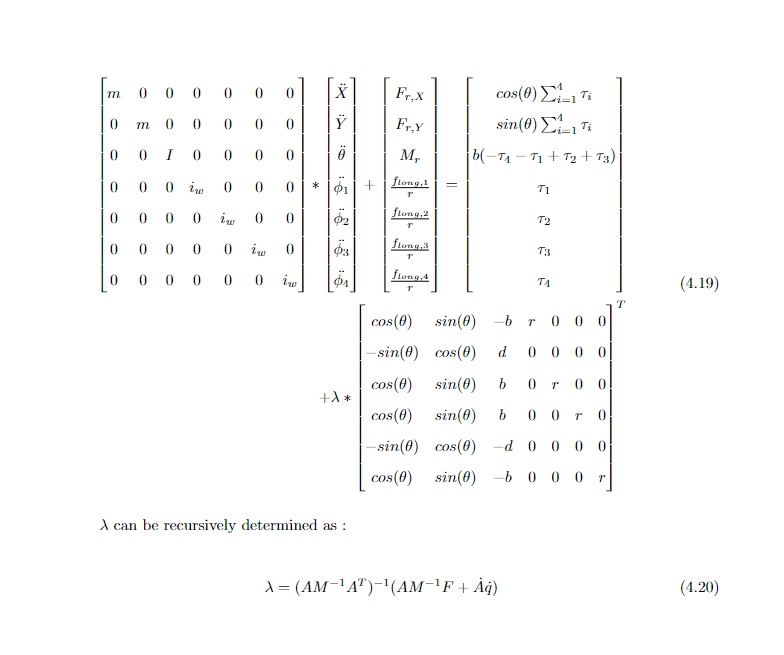

% mass matrix:

M = [m 0 0 0 0 0 0;
    0 m 0 0 0 0 0;
    0 0 I 0 0 0 0;
    0 0 0 i_w 0 0 0;
    0 0 0 0 i_w 0 0;
    0 0 0 0 0 i_w 0;
    0 0 0 0 0 0 0 i_w];

% let slip angle for each wheel be denoted by alpha_i

%alpha_i = invTan(V_y/V_x), where V_y = x_projection_of_ICR * yaw_rate ;
%V_x = phi_i_dot (can be calculated from wheel odometery)


